# Gridded NORA3 data: automated and remote data extraction

The data from the NORA3 atmosphere hindcast are extracted from the THREDDS Data Server of the Norwegian Meteorological Institute [2]. A summary of the NORA3 data and their potential is available in [1]. The data sources are netcdf files and the OPeNDAP framework is used to read the data without downloading them. The data are resampled as gridded data. The time resolution is 1 h and the horizontal resolution is ca. 3 km.

References

[1] Solbrekke, I. M., Sorteberg, A., & Haakenstad, H. (2021). Norwegian hindcast archive (NORA3)–A validation of offshore wind resources in the North Sea and Norwegian Sea. Wind Energy Science Discussions, 1-31.

[2] [https://thredds.met.no](https://thredds.met.no/)  

## Definition of the parameters

Data from storm Aina (2017-12-08) at 4 am are extracted.

targetYear = 2017; 
targetMonth = 12;
targetDay = 08;
targetHour = 4;

resolution = 0.025; % resolution for latitude and longitude in degrees (< 3 km)
targetLat = [53 73]; % target latitude (between 52 and 74)
targetLon = [-20 20];  % target longitude (between -11 and 42)

## Extract the data on the 2017-12-08 at 4 am for Scandinavia

% Grid definition
Nz = 7; % number of heights in the NORA 3 file that is explored
[lon,lat] = meshgrid(targetLon(1):resolution:targetLon(end),targetLat(1):resolution:targetLat(end));
[Nlat,Nlon]=size(lat);
% Preallocate the output
Nhour = numel(targetHour);
Ntot = numel(targetYear)*numel(targetMonth)*numel(targetDay)*Nhour; % number of data points
U = NaN(Ntot,Nlat,Nlon,Nz); %  Mean wind speed profile
D = NaN(Ntot,Nlat,Nlon,Nz); %  Mean wind direction profile
time = NaT(1,Ntot);


oo= 1;
for ii=1:numel(targetYear)
    for jj=1:numel(targetMonth)
        for kk=1:numel(targetDay)
            for ll=1:numel(targetHour)
                tic
                [mydata] = getNORA3(targetLat,targetLon,targetYear(ii),targetMonth(jj),targetDay(kk),...
                    targetHour(ll),resolution);
                U(oo,:,:,:)= mydata.U;
                D(oo,:,:,:) = mydata.D;
                time(oo)= mydata.time;
                oo=oo+1;
                toc
            end
        end
    end
end

Elapsed time is 153.457303 seconds.


## Wind speed map

Only display data above the ocean

load('world.mat'); % Load borders of countries
ii= 1

ii = 1

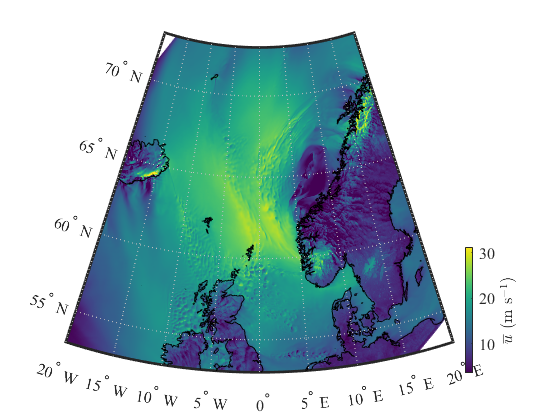

clf;close all;
figure
oldU = squeeze(U(ii,:,:,1));
hold off

if  license('test','MAP_Toolbox')
    worldmap(targetLat,targetLon)
    geoshow(lat,lon,oldU, 'DisplayType','surface')
    g = geoshow(world.lat,world.lon,'DisplayType','Line');
    g.Color = [0 0 0];
else
    imagesc(lon(1,:),lat(:,1),oldU);axis xy
    hold on
    plot(world.lon,world.lat,'k')
end
hold on

if exist('viridis.m','file')
    colormap('viridis');
else
    colormap('hot');
end
caxis([quantile(reshape(U,1,[]),0.01) quantile(reshape(U,1,[]),0.99)])
if ii==1 || ~isvalid(cb2),    cb2 = colorbar('location','eastoutside');end
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

x1=get(gca,'position');x=get(cb2,'Position');x(3)=0.015; x(4)=0.3;set(cb2,'Position',x);set(gca,'position',x1)
cb2.Label.String = '$\overline{u}$ (m s$^{-1}$)';
cb2.Label.Interpreter = 'latex';
cb2.AxisLocation = 'out';

set(gcf,'color','w')

## Wind speed profile above the ocean

The function interpU interpolates the mean wind speed profile using a least-square fit of the Deaves and Harris model [1,2] to the modelled profile. In this example, the target location is on the western coast of Bergen. The surface roughness is estimated using the Charnock equation [3] and the logarithmic profile of mean wind speed under neutral conditions.

References

[1] Harris, R. I., & Deaves, D. M. (1980, November). The structure of strong winds, wind engineering in the eighties. In Proc. CIRIA Conf.

[2] ESDU. (1985). ESDU 85020-Characteristics of atmospheric turbulence near the ground. Part II: single point data for strong winds (neutral atmosphere.

[3] Charnock, H. (1956). Statistics and aerodynamics of the sea surface. Nature, 177(4498), 62-63.

kappa = 0.41; % von karman constant
a_c = 0.011; % Charnock coefficient with values between 0.01 and 0.02
[~,indLat] = min(abs(lat(:,1)-60)); % identify the indice of the target latitude
[~,indLon] = min(abs(lon(1,:)-5)); % identify the indice of the target longitude
oldZ = mydata.z;
oldU = squeeze(U(ii,indLat,indLon,:)); % old wind speed profile from the NORA3 database
newZ = logspace(log10(oldZ(1)),log10(oldZ(end)),100); % new hright vector with logarithmic spacing

[z0] = getz0_charnock(oldU(1),oldZ(1),a_c); % Get the roughness of the sea by solving Charnock's equation

Charnock relationship leads to zsea = 1.5e-03 m 


u_star = oldU(1)*kappa./log(oldZ(1)./z0);  % frictionv velocity estimated with the logarithmic mean wind speed profile
% The way u_star is calculated works only for neutral conditions, but it is here OK to apply it for diabatic
% conditions as the focus is only on the interpolation, not the coefficients of the Deaves and Harris mdoel.
[newU,rmse] = interpU(oldZ,z0,oldU,newZ,u_star);
fprintf('RMSE between the fitted and modelled mean wind speed profile is %1.1f m/s \n',rmse)

RMSE between the fitted and modelled mean wind speed profile is 0.2 m/s 


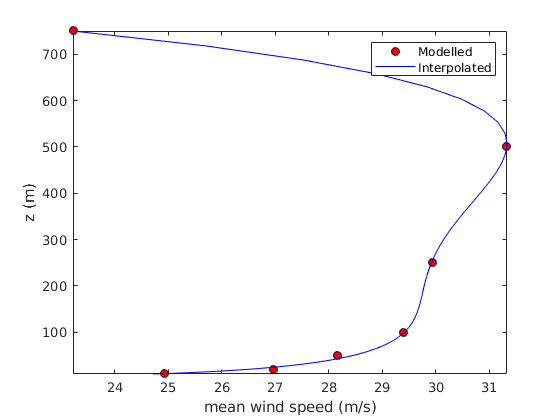

 
figure
plot(oldU,oldZ,'ko','markerfacecolor','r')
hold on
plot(newU,newZ,'b');
legend('Modelled','Interpolated')
ylabel('z (m)')
xlabel('mean wind speed (m/s)')
axis tight